# Spherical shell coordinates

clear
set_demo_defaults;
R_mars = 3389508;    % [m] Mars' mean radius 
grav = 3.711;   % [m/s^2] grav. acceleration on Mars

We have seen that moving to cylindrical coordinates removed the ambiguity in the interpretation of the polar recharge. To properly incorporate precipitation we need to go to a geometry with a meaningful surface area. In 1D linear coordinates the surface area is an arbitrary function of the undetermined width. In cylindrical coordinates we have a proper surface area, but given that the southern highlands aquifer stretches halfway through the northern hemisphere the we have a huge error in the actual surface area compared to a sphere, see figure. The same would be true for any estimate of the actual groundwater volume.

theta_bnd = acos(1/3);
theta_bnd_deg = rad2deg(theta_bnd)

theta_bnd_deg = 70.5288

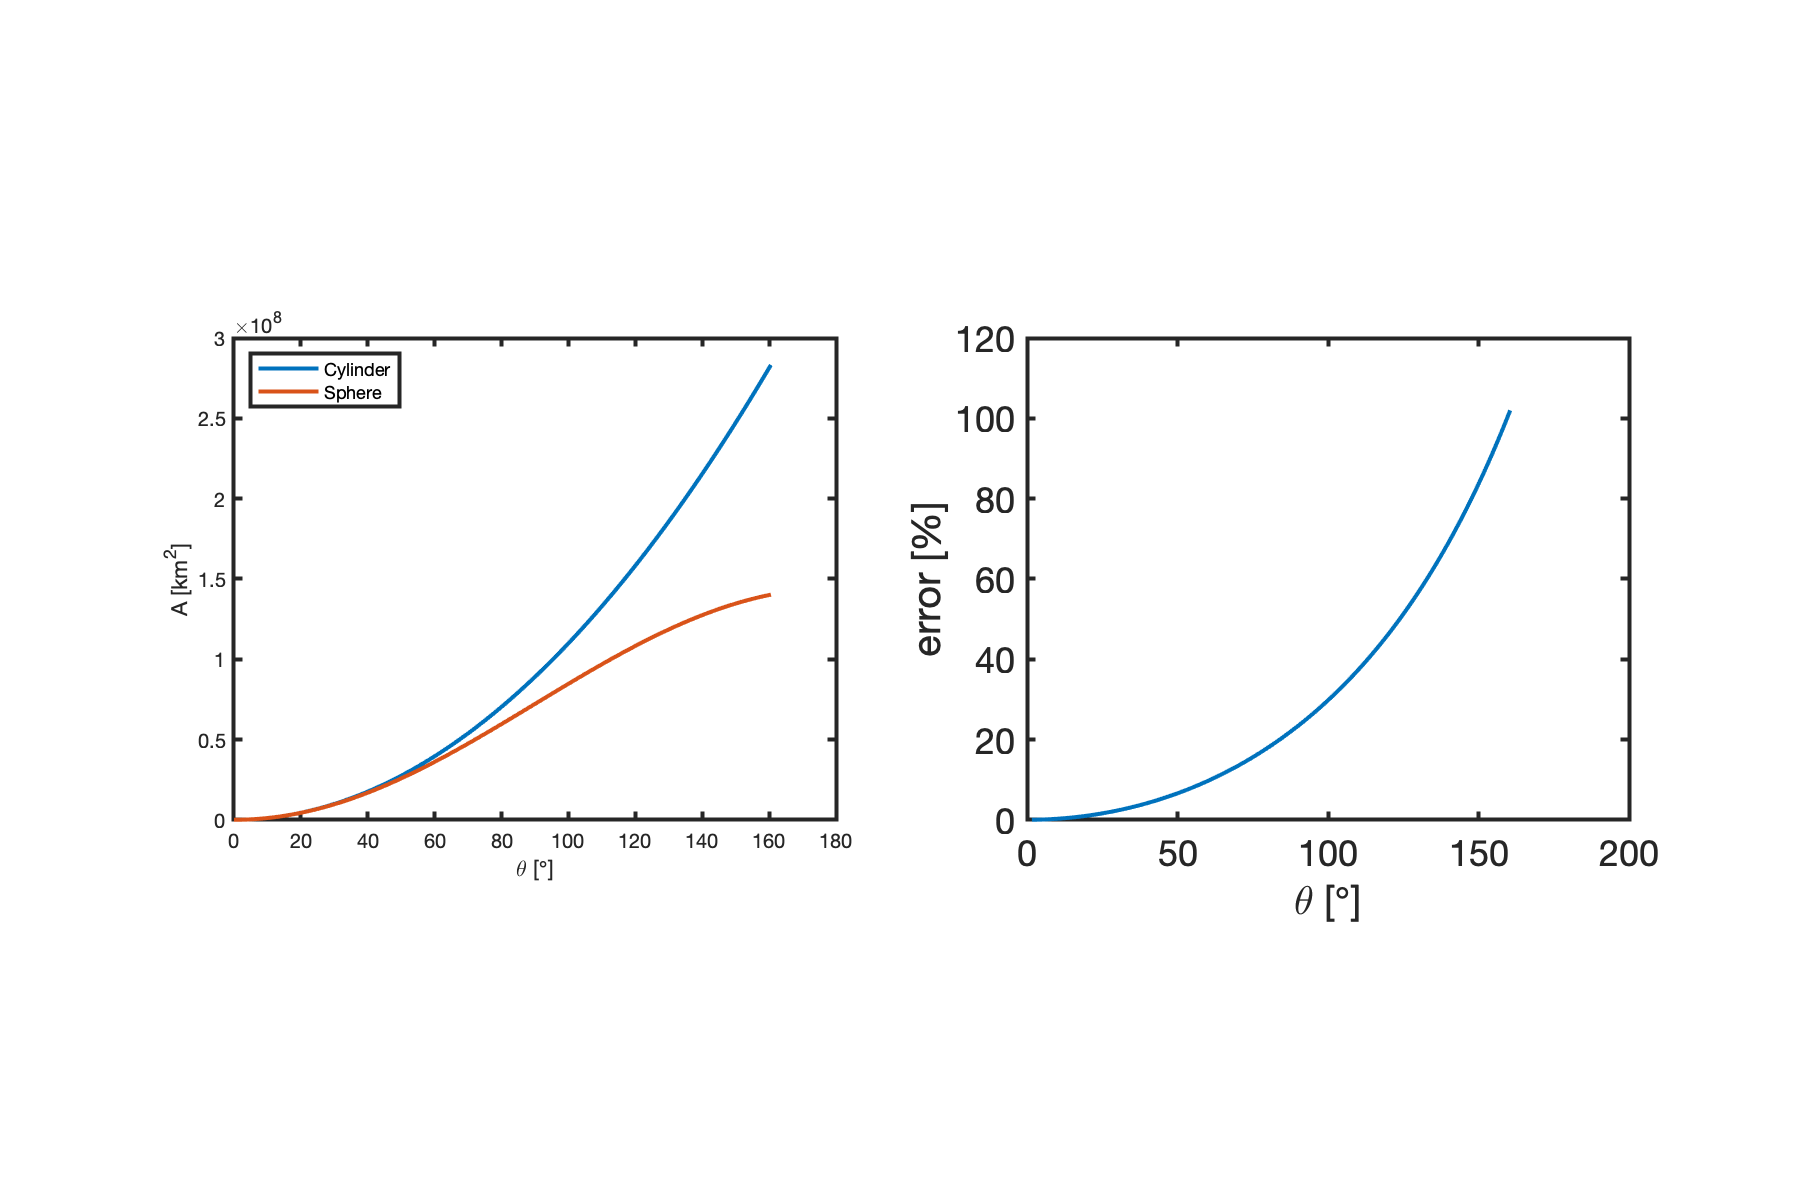


theta_vec = linspace(0,90+theta_bnd_deg,100);
l = R_mars*deg2rad(theta_vec); % [m] distance to dichotomy bnd

A_cyl = pi*l.^2;
A_cap = 2*pi*R_mars^2*(1-cos(deg2rad(theta_vec)));

figure('position',[10 10 900 600])
subplot 121
plot(theta_vec,A_cyl/1e6,theta_vec,A_cap/1e6)
xlabel '\theta [\circ]', ylabel 'A [km^2]', pbaspect([1 .8 1])
legend('Cylinder','Sphere','location','northwest')

subplot 122
plot(theta_vec,(A_cyl-A_cap)./A_cap*100)
xlabel '\theta [\circ]', ylabel 'error [%]', pbaspect([1 .8 1])

## Spherical coordinates

This motivates us to discretize the discrete operators in spherical coordinates. The definition of standard variables in spherical coordinates is shown in the figure below.

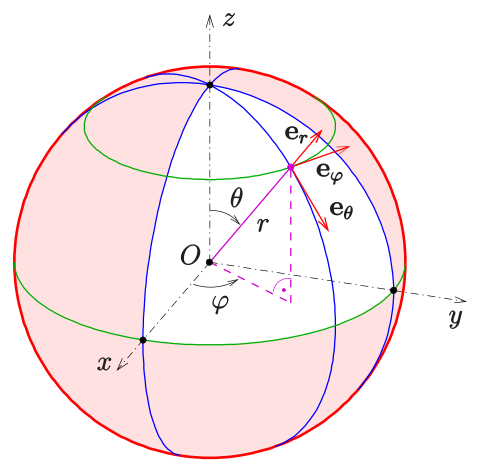

Here $r$ is the radial coordinate, $\theta$ is the co-lattitude and $\varphi$ is the circumferecial coordinate. The associated definition of the gradient and the divergence 

- 
$$\nabla h = \frac{\partial h}{\partial r} \hat{\mathbf{\rho}} + \frac{1}{r}\frac{\partial h}{\partial\theta} \hat{\mathbf{\theta}} +  \frac{1}{r\sin\theta}\frac{\partial h}{\partial \varphi} \hat{\mathbf{\varphi}}$$


- 
$$\nabla\cdot\mathbf{q} = \frac{1}{r^2} \frac{\partial(r^2 q_r)}{\partial r}+ \frac{1}{r\sin(\theta)} \frac{\partial }{\partial\theta}\left(\sin(\theta)\,q_\theta\right)+ \frac{1}{r\,\sin(\theta)} \frac{\partial q_\varphi}{\partial \varphi}$$


where $\mathbf{q} = [q_r \, q_\theta,\,q_\varphi]$.

The southern highlands aquifer is in a spherical shell, so that $r=R_\mathrm{Mars}$ is fixed. To obtain a one-dimensional model we assume no change in the circumferential dirrection, $\varphi$, so that $\partial/\partial\varphi=0$. Therefore, the remaining independent variable is the co-lattitude, $\theta$, and  one-dimensional operators in sherical shell geometry, $x=\theta$, are

- 
$$\nabla h =  \frac{1}{R_\mathrm{Mars}}\frac{\mathrm{d} h}{\mathrm{d} x} $$


- 
$$\nabla\cdot\mathbf{q} =  \frac{1}{R_\mathrm{Mars}\sin (x)} \frac{\mathrm{d} }{\mathrm{d}x}\left(\sin( x)\,q\right)$$


In spherical shell coordinates both the divergence and the gradient change. Again we have to amend the function `build_ops.m`.  

### Discrete operators

The discrete divergence and gradient matrix in spherical shell geometry can therefore be obtained as follows:

Grid.xmin = 0.1; Grid.xmax = 1; Grid.Nx = 35;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);

% Modification for spherical shell
Grid.R_shell = R_mars;
Rf = spdiags(sin(Grid.xf),0,Grid.Nx+1,Grid.Nx+1);
Rcinv = spdiags(1./(Grid.R_shell*sin(Grid.xc)),0,Grid.Nx,Grid.Nx);
D = Rcinv*D*Rf;
G = G/Grid.R_shell;
L = -D*G;

Similar to the cylindrical coordinates we evaluate terms outside the divergence at cell centers and terms inside the divergence at cell faces.

## Spherical shell aquifer with precipitation

#### Dimensional

The equations for the steady confined aquifer with precipitation on a spherical shell are given by 

$\frac{1}{R_\mathrm{Mars}\sin (\theta)} \frac{\mathrm{d} }{\mathrm{d}\theta}\left(\sin(\theta)\,bK  \frac{1}{R_\mathrm{Mars}}\frac{\mathrm{d} h}{\mathrm{d} x} \right)=q_p$ on $\theta\in \left[0,\,\theta_b\right]$

with the boundary conditions

$\left.\frac{\mathrm{d}h}{\mathrm{d}\theta}\right|_0=0$ on $h(\theta_b)=h_o$

Th paramter values are as before

The parameter values are as before

yr2s = 60^2*24*365.25;  % second per year
rho = 1e3;              % [kg/m^3] desity of water 
grav = 3.711;           % [m/s^2] grav. acceleration on Mars
k = 1e-11;              % [m^2] permeability (Hanna & Phillips 2005)
mu = 1e-3;              % [Pa s] water viscosity
ho = -500;              % [m] sea level
b = 5e3;                % [m] aquifer thickness
theta_bnd = pi-acos(1/3);  % [rad] angel dichotomy boundray from south pole
% derived values
K = k*rho*grav/mu;      % [m/s] hydraulic conductivity

#### Dimensionless 

The angle, $\theta$, in radiants is defined as ratio of the arc length, $s$, to the radius, $R$, of the circle, $\theta = s/R$, and hence dimensionless and of order one. We define the characteristic scale $h_c=q_pR_\mathrm{Mars}^2/(bK)$ and the associated dimensionless head $h'=(h-h_o)/h_c$. This induces the scale $q_c = q_pR_\mathrm{Mars}/b$ for the flux. The dimensionless equations are

$-\frac{1}{\sin\theta}\frac{\mathrm{d}}{\mathrm{d}\theta}\left(\sin\theta\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right)=1$ on $\theta \in \left[0,\,\theta_b\right]$

with the boundary conditions 

$\left.\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right|_0 = 0$ and $h'(\theta_b)=0$.

The dimensionless flux is simply $q'=-\frac{\mathrm{d}h'}{\mathrm{d}\theta}$. The only dimensionless parameter is therfore the angle of the dichotomy boundary $\theta_b$. 

#### Analytic solutions

The dimensionless analytic solution is given by

$h' = \log\left(\frac{\cos\theta+1}{\cos\theta_b+1}\right)$ and $q' = \frac{1-\cos\theta}{\sin\theta} = \csc\theta - \cot\theta$.

hD_ana = @(theta,theta_bnd) log((cos(theta)+1)/(cos(theta_bnd)+1));
qD_ana = @(theta) csc(theta) - cot(theta);

The solution is show in the figure below for increasing co-lattidudes of the dichotomy boundary 

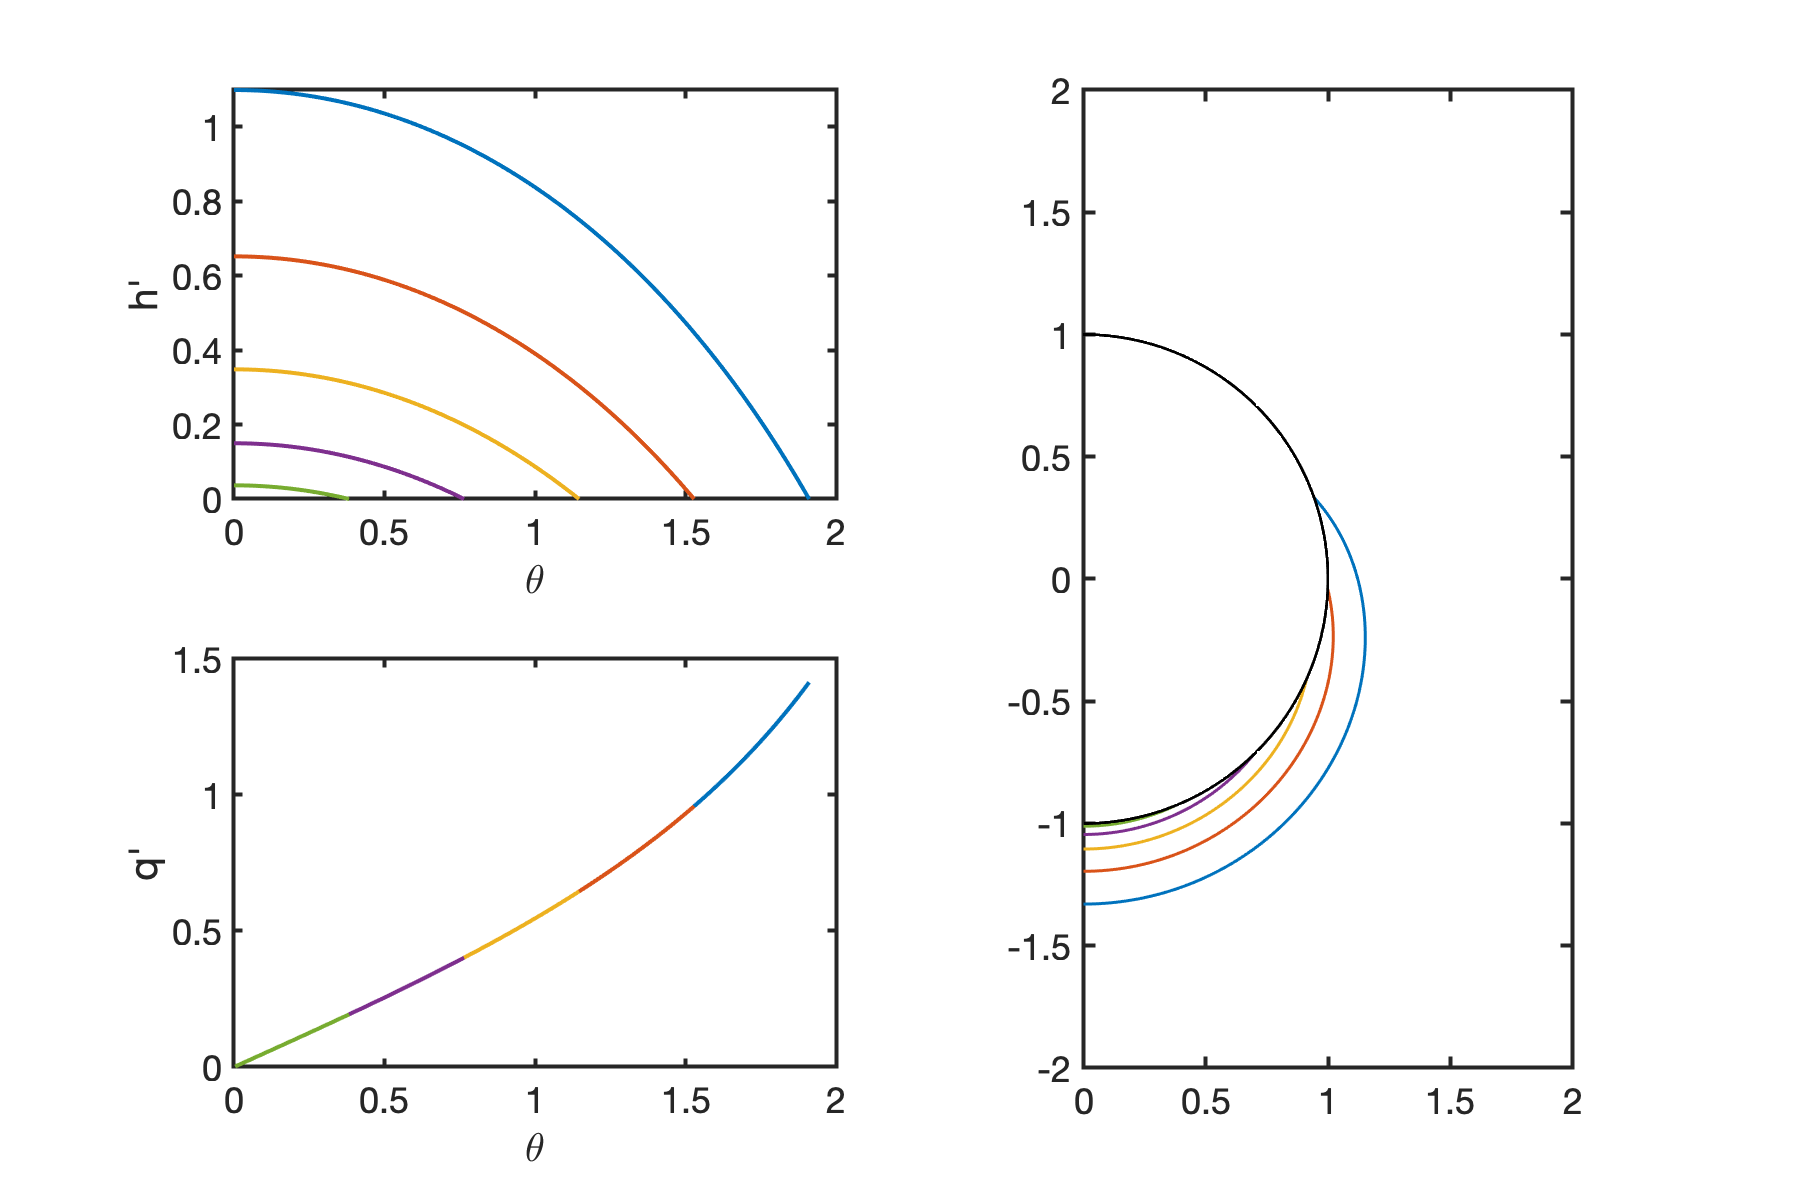

h_scale_plot = 0.3;
theta_bnd_vec = [theta_bnd:-theta_bnd/5:theta_bnd/5];

figure('position',[10 10 900 600])
for i = 1:length(theta_bnd_vec)
    theta =  linspace(0,theta_bnd_vec(i),1e2);
    subplot(2,2,1)
    plot(theta,hD_ana(theta,theta_bnd_vec(i))); hold on
    subplot(2,2,3)
    plot(theta,qD_ana(theta)); hold on
    subplot(2,2,[2 4])
    x_h = (1+hD_ana(theta,theta_bnd_vec(i))*h_scale_plot).*sin(theta); 
    z_h = (1+hD_ana(theta,theta_bnd_vec(i))*h_scale_plot).*cos(theta);
    plot(x_h,-z_h,'-','linewidth',1.5), hold on
end
subplot(2,2,1)
ylabel 'h''', xlabel '\theta'
subplot(2,2,3)
ylabel 'q''', xlabel '\theta'
subplot(2,2,[2 4])
theta_sphere = linspace(0,pi,5e2);
x_base = sin(theta_sphere);
z_base = cos(theta_sphere);
plot(x_base,z_base,'k','linewidth',1.5)
axis equal
xlim([0 2]), ylim([-2 2])